## step 50 [deg] simulations for nominal tracking with lqr


% simulate value with no antiwindup filter step 50 [deg] nominal

step_amplitude = 50;

data = sim("lab3_lqr_robust_sim.slx");

t = data.ScopeData1.time;
tetha_h = data.ScopeData1.signals(1).values;  
tetha_d = data.ScopeData1.signals(2).values;
ref_signal = data.ScopeData1.signals(3).values;

save("lab3_lqr_robust_sim.mat",'t','tetha_h','tetha_d','ref_signal');



## Stampa grafico

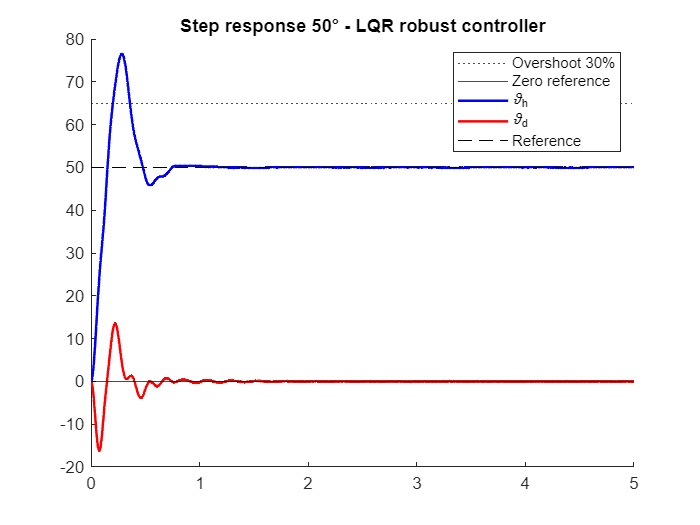


% grafico step 50 deg

load("lab3_lqr_robust_sim.mat");
figure;
% plot(t,ref,'k--');
yline(65, 'k:','LineWidth', 0.5, 'DisplayName', 'Overshoot 30%');
yline(0, 'k','LineWidth', 0.5, 'DisplayName', 'Zero reference');
hold on 
plot(t,tetha_h,'b','LineWidth', 1.5, 'DisplayName', '\vartheta_h');
plot(t,tetha_d,'r','LineWidth', 1.5, 'DisplayName', '\vartheta_d');
plot(t,ref_signal,'k--','LineWidth', 0.5, 'DisplayName', 'Reference');
axis([0 5 -20 80])
title('Step response 50° - LQR robust controller')
legend
hold off

#### Step response parameters


step_50_wind_up_nominal_lqr = stepinfo(tetha_h, t, 50, 'SettlingTimeThreshold', 0.05);
disp(step_50_wind_up_nominal_lqr);

         RiseTime: 0.1120
    TransientTime: 0.6090
     SettlingTime: 0.6090
      SettlingMin: 45.1800
      SettlingMax: 76.5000
        Overshoot: 53
       Undershoot: 0
             Peak: 76.5000
         PeakTime: 0.2780

